# Exercise #2 WLAN Custom Channel Model

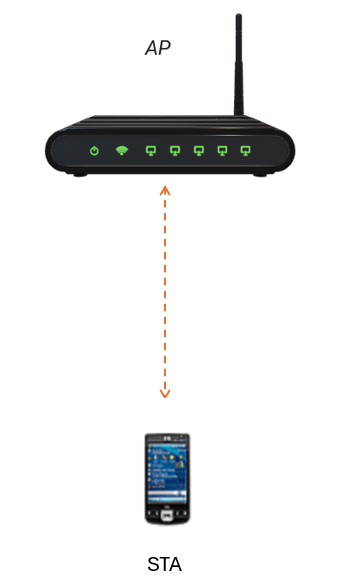

#### In this exercise, You will learn how to  

- Configure and create WLAN nodes and networks 

- Plug in a custom channel model in the simulation 

- Visualize the performance

- Perform cleanup by closing previously opened windows and figures. 

clear all;
all_figs = findall(0, 'type', 'figure');close(all_figs);

- Initialize the random number generator for reproducibility

- Set the simulation time

- Initialize the network simulator

- Launch the wireless network viewer to visualize the network during simulation

- Define AP and STA position 

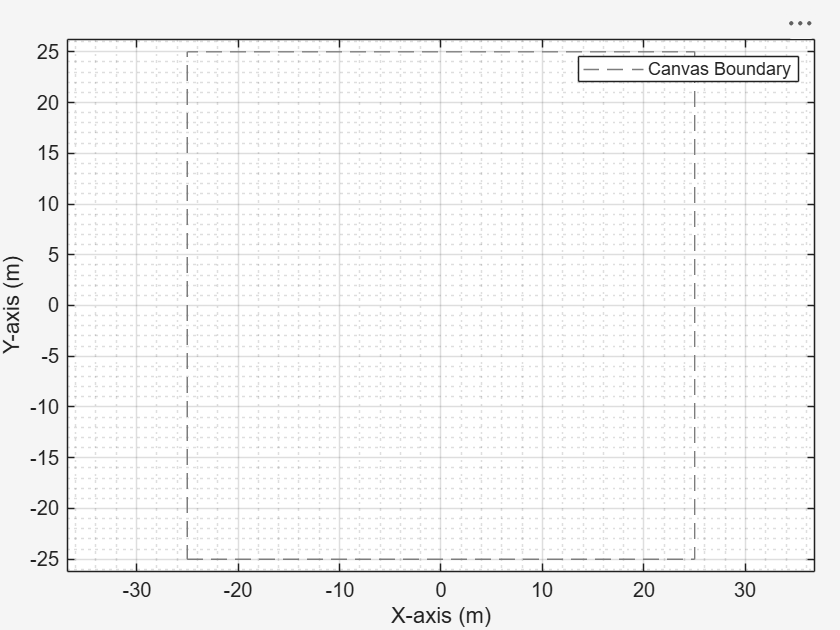

rng(1,"twister");
TU              = 1024e-6; 
simulationTime  = 100*TU;  
networkSimulator = wirelessNetworkSimulator.init;
networkViewerObj = wirelessNetworkViewer(CanvasSize=[50 50 0]);

AP_pos  = [0,0,0];
STA_pos = [5,5,0];
band        = 2.4;
channel     = 7;
bandwidth   = 20e6;
distance = norm(AP_pos - STA_pos);
c = physconst('LightSpeed');
lambda = c/(band*1e9);
pathLoss = 10*log10(((4*pi*distance)/(lambda))^2)

pathLoss = 57.0417

#### Configure WLAN AP

APCfg = wlanDeviceConfig(...
    "Mode","AP",...
    "TransmissionFormat", "HE-SU", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth, ...
    "TransmitPower",0);

#### Create a WLAN Access Point (AP)

macmodel = "full-mac";
phymodel = "full-phy";

Note: All nodes on the network must have same MAC and PHY abstractions  

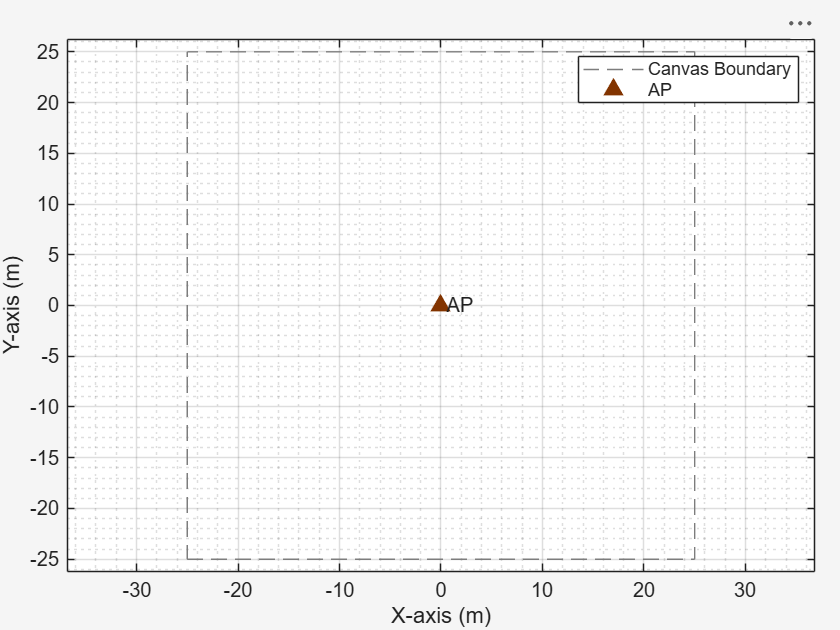

AP = wlanNode(...
    "Name","AP",...
    "Position",AP_pos, ...
    "DeviceConfig",APCfg,...    
    "MACModel",macmodel,...
    "PHYModel",phymodel); 
addNodes(networkViewerObj,AP,Type="AP");

#### Create a WLAN Station (STA) and set up the BSS

STACfg = wlanDeviceConfig(...
    "Mode","STA",...
    "TransmissionFormat","HE-SU", ...
    "BandAndChannel",[band, channel], ...
    "ChannelBandwidth",bandwidth, ...
    "TransmitPower",0);

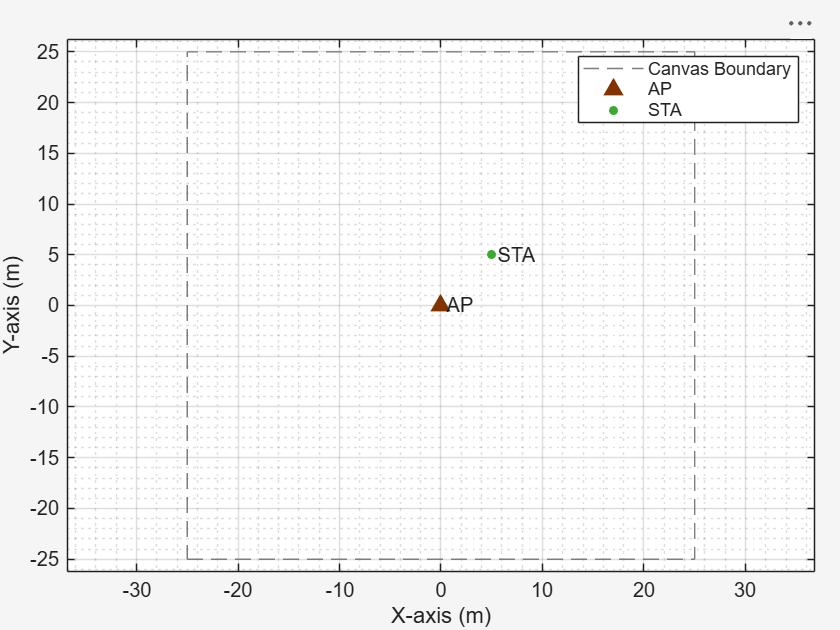

STA = wlanNode(...
    "Name","STA",...
    "Position",STA_pos, ...
    "DeviceConfig",STACfg,...    
    "MACModel",macmodel,...
    "PHYModel",phymodel); 
addNodes(networkViewerObj,STA,Type="STA");

### Associate AP with STA and create a BSS

associateStations(AP,STA,FullBufferTraffic="on");
wlanNodes = [AP, STA];
addNodes(networkSimulator,wlanNodes)

# Task #1/3 Add Custom Channel Model to Network Simulator

**Instructions to complete the task**

Add a custom channel model to the network simulator.

Use the `addChannelModel()` function to add the channel model to the simulation.

Hint: Type `doc addChannelModel` in the MATLAB Command Window and refer to the *Syntax* section.

Pass the following arguments:

- `networkSimulator`

- `@myCustomChannel`

**Note: You will implement your channel model in the **`myCustomChannel`** function in Task 3.**

% <enter code below>
addChannelModel(networkSimulator,@myCustomChannel);

#### Enable capture of IQ samples

Use the `wirelessIQLogger`  to log in-phase and quadrature (IQ) samples from wireless nodes in a wireless network simulation.

enableIQCapture = true;
if enableIQCapture
    iqSampleObj = wirelessIQLogger(wlanNodes);
end

#### Enable packet visualization

- Use the **wirelessTrafficViewer** object to monitor wireless nodes 

- View node state transitions over time 

- See channel occupancy for each node 

- Visualize packet transmissions over time 

viewerObj = wirelessTrafficViewer;
addNodes(viewerObj,wlanNodes);

# Task 2/3: Run the simulation

Runs the discrete-event simulator in MATLAB to execute the network model.

**Instructions to complete the task**

Use addNodes() function to add Bluetooth LE nodes to the network simulator   

Type `doc wirelessnetworksimulator.run` in the MATLAB Command Window, and see the "Syntax" section.

Note : use the following values as arguments 

- networkSimulator

- simulationTime

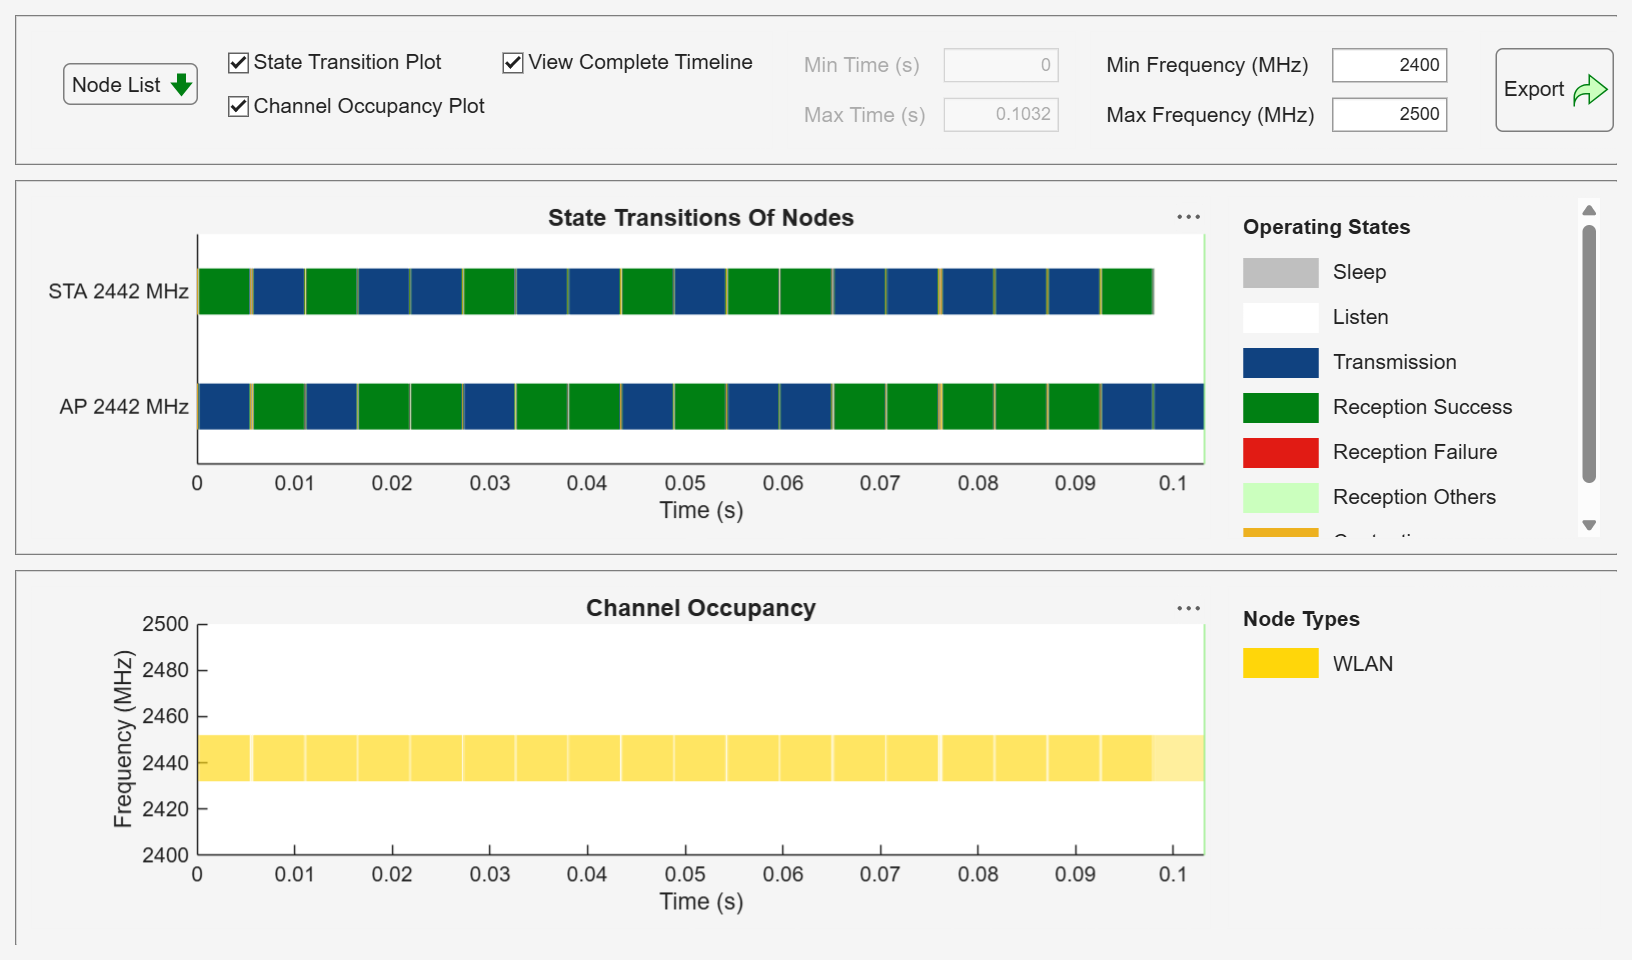

% <enter code below>
run (networkSimulator,simulationTime)

# Task #3/3 Implement custom path loss for the channel 

**Note: Before starting Task 3, place a breakpoint inside the **`myCustomChannel`** function at line **`outputData = txData;`** and run the simulation**

#### **Description of the Task** 

Follow these steps to create a custom channel model:

- The simulator passes information about the receiver and transmitter nodes as inputs to the custom function. 

- Apply free-space path loss between the base station and UE nodes. 

- Apply the custom channel model to the transmitted packets. 

`myCustomChannel` is a user-defined callback function invoked by the simulation engine whenever a packet is exchanged between any two nodes in the simulated network.

**Inputs to the function:**

- **rxInfo** (receiver information) includes: 

- ID 

- Position 

- Velocity 

- Additional receiver-related parameters 

- **txData** (transmitter data) includes: 

- Transmitter ID 

- Transmitter position 

- Transmitter velocity 

- Transmit power 

- Center frequency 

- Bandwidth 

- Sample rate 

- Antenna configuration 

- Transmitted data and other relevant parameters

**Instructions to complete the task**

Large-Scale Fading: pathLoss = 10*log10(((4*pi*distance)/(lambda))^2);

**Step 1: Calculate the wavelength of operation**

**You need to type:**

`c = physconst('LightSpeed');`

`lambda = c/txData.CenterFrequency;`

**Step-2 Calculate the distance between receiver and transmitter **

Use the `norm()` function to compute the distance between the UE and gNB.

distance = norm(p1 − p2), where p1 = (x1, y1, z1) and p2 = (x2, y2, z2).

This calculates √((x1 − x2)² + (y1 − y2)² + (z1 − z2)²).

**You need to type: **

`distance = norm(txData.TransmitterPosition - rxInfo.Position);`

**Step-3 Calculate the pathloss **

**You need to type: **

`pathLoss = 10*log10(((4*pi*distance)/(lambda))^2);`

**Step-4 Convert pathloss to linear scale  **

**You need to type: **

`scale = db2mag(-pathLoss);`

function outputData = myCustomChannel(rxInfo,txData)
outputData = txData;
% Step-1
c = physconst('LightSpeed');
lambda = c/txData.CenterFrequency;
% Step-2
distance = norm(txData.TransmitterPosition - rxInfo.Position);
% Step-3
pathLoss = 10*log10(((4*pi*distance)/(lambda))^2);
outputData.Power = outputData.Power - pathLoss;
% Step-4
scale = db2mag(-pathLoss);
outputData.Data = outputData.Data*scale;
end

#### IQ sample visualization

enableIQVisualization = true; 
if enableIQVisualization
    fileName = iqSampleObj(1).FileName;
    iqData = load(fileName);
    signalAnalyzer(iqData.Waveform,SampleRate=iqData.Fs);
end

Copyright 2024-2025 The MathWorks, Inc